# 2D FEM

## Step 1 - Poisson problem on a unit square

Generate a 1x1 square mesh using GMSH (https://gmsh.info), then export it as an .m file.

 Load the mesh information by running the mesh file

Visualize the mesh using the trimesh function

Create a function FEM2D_s1.m that solves a basic electrostatic FEM problem on the given mesh, with $\varphi = 0$ on the edges.

### Something we will need... computation of the shape function gradients

For a triangular element, the magnetic potential $A_z$ is expressed in terms of the shape functions $L_i(x,y), \ L_j(x,y), \ L_k(x,y)$and the and the nodal values of $A_z$ at the element's vertices:

$L_i(x,y) = \frac{S_i(x,y)}{S}
$;     $L_j(x,y) = \frac{S_j(x,y)}{S}
$;     $L_k(x,y) = \frac{S_k(x,y)}{S}
$


$$S = \frac{1}{2} \mathrm{det} [\text{PV}] =
\frac{1}{2} \mathrm{det} \left[ \matrix{
1 & x_i & y_i \cr
1 & x_j & y_j \cr
1 & x_k & y_k
}\right].
\]$$


Computing the inverse of PV:


$$\[
\text{PV}^{-1} =\left[
\matrix{
a_i & a_j & a_k \cr
b_i & b_j & b_k \cr
c_i & c_j & c_k
}\right]
\]$$



$$\[
[\text{\nabla L}] = \left[
\matrix{
b_i & b_j & b_k \cr
c_i & c_j & c_k
}\right]
=
\text{PV}^{-1}(2{:}3, :).
\]$$


## Step 2 (homework!) - Capacitance of RG-59 coaxial cable

RG-59 coaxial cable consists of an inner conductor having radius 0.292 mm, an outer conductor having radius 1.855 mm, and a polyethylene spacing material having relative permittivity 2.25.

Compute the per-unit-length capacitance of the cable.

SOLUTION: C′=67.7 pF/m

## Step 3 - Inductance of Two Wire Single Phase Transmission Line

Consider two cylindrical conductors A and B of radius rA=rB, carrying 1 A in opposite directions. 

Conductor A is at a distance D from conductor B and both are of length L. Compute the per-unit-length inductance of the transmission line (TL).

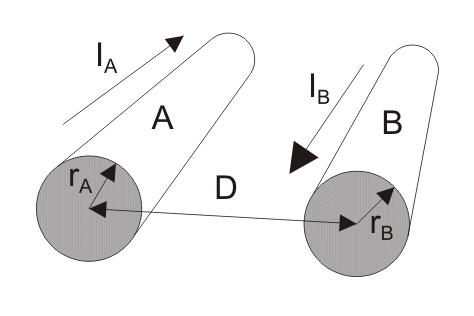

### Theory (magnetostatics)

Starting from$\nabla \times \left(\frac{1}{\mu}\mathbf{B}\right) = \mathbf{J}$

Substituting $\(\mathbf{B} = \nabla \times \mathbf{A}\)$ and applying the identity:


$$\nabla \times (\nabla \times \mathbf{A}) = \nabla (\nabla \cdot \mathbf{A}) - \nabla^2 \mathbf{A}$$


For magnetostatics in the Couloumb gauge $\(\nabla \cdot \mathbf{A} = 0\)$ one has:


$$\[
\nabla\cdot\left(\frac{1}{\mu} \nabla \mathbf{A} \right)= \mathbf{J}
\]$$


The currents flow into/out of the $z-$plane, hence $\mathbf{A} = A_z(x,y) \mathbf{\hat{k}}$ and $\mathbf{J} = J_z(x,y) \mathbf{\hat{k}}$:

$\nabla\cdot\left(\frac{1}{\mu_r} \nabla A_z \right)=\mu_0 J_z$    Poisson-type equation for vector potential (z-component)

---

Create and visualize mesh:

### Problem setup

Define cross section of TL conductors (circles of radius $r=r_A=r_B$)


$$J_z = \frac{I}{\pi r^2} \quad \text{(for conductor A)}$$



$$J_z = -\frac{I}{\pi r^2} \quad \text{(for conductor B)}$$


Now we need to compute $B_x(x,y)\mathbf{\hat{i}}$ and $B_y(x,y)\mathbf{\hat{j}}$.

The gradient of $A_z
$ within an element is constant and given by:


$$\[
B_x = -\frac{\partial A_z}{\partial y}, \quad
B_y = \frac{\partial A_z}{\partial x}
\]$$


% compute gradient of phi
% [gradAzx, gradAzy] = computeGradient2D(Az, msh.POS(:,1:2), msh.TRIANGLES);

% visualize the gradient
% visualizeFieldContour(Az, msh.POS(:,1:2), msh.TRIANGLES, Bx, By); % sqrt(Bx.^2+By.^2)

### Inductance computation

Compute magnetic energy density


$$W_{m,\text{el}} = \int_{\Omega_\text{el}} \frac{1}{2 \mu} \left( B_x^2 + B_y^2 \right) \, d\Omega$$



$$W_{m,\text{el}} = \frac{1}{2 \mu} |\mathbf{B}|^2 \cdot \text{Area}_\text{el}$$


% Bx and By at element barycenter needed
%{
nel = size(msh.TRIANGLES,1);
Bx_c = zeros(nel,1);
By_c = zeros(nel,1);
for iel=1:nel
    nodes = msh.TRIANGLES(iel, :);
    coords = msh.POS(nodes, :);

    % Shape function values at the element barycenter
    L = [1/3, 1/3, 1/3]; % Linear elements give equal weights at barycenter

    % Interpolate Bx and By
    Bx_c(iel) = L(1)*Bx(nodes(1)) +  L(2)*Bx(nodes(2)) +  L(3)*Bx(nodes(3));
    By_c(iel) = L(1)*By(nodes(1)) +  L(2)*By(nodes(2)) +  L(3)*By(nodes(3));
end
%}

%{
% Get the coordinates of the triangle vertices for all elements
x1 = x(T(:, 1),1); x2 = x(T(:, 2),1); x3 = x(T(:, 3),1);
y1 = x(T(:, 1),2); y2 = x(T(:, 2),2); y3 = x(T(:, 3),2);
% Compute the area of each triangle using determinant-based formula
Area = 0.5 * ((x2 - x1) .* (y3 - y1) - (x3 - x1) .* (y2 - y1));
%}

% compute magnetic energy density
% ...

Total magnetic energy:


$$W_m = \sum_{\text{elements}} W_{m,\text{el}}$$


% compute total magnetic energy


From energy density, compute inducance:


$$W_m = \frac{1}{2}LI^2 \qquad \longrightarrow \qquad L=\frac{2 W_m}{I^2}$$


Compare to analytical expression $L=\frac{\mu_0}{\pi}\ln{\left(\frac{D}{r}\right)} \quad [\mathrm{H/m}]$: